global K q Vg n Voc Isc1 T1 Ko S1;
K = 1.381e-23;                      % Boltzmann Constant
q = 1.6e-19;                        % Charge 
Vg = 1.12;                          % Band Gap
n = 72;                             % Number of cells
Voc = 44.8;                         % V open circuit
Isc1 = 5.5;                         % Short circuit current STC
T1 = 298;                           % STC tempreature
Ko = 0.00065;                       % Temperature Coefficient
S1 = 1000;                          % Light intensity
VMPP = 36.5;                         % Voltage of max power
IMPP = 5.1;

T = 300;                             % temp in kelvin
irrad = 1000 ;                       %irradiance in watt/m2


Il = IrradianceCurrent(298,1000);   %//// Light current w.r.t temp and irradiance %%%keeep IT LIKE THIS AS THIS IS THE IL1 USED IN THE CODE
Il1 = Isc1;                         % Short circuit current STC = Light current
%Is1 = ReverseCurrentSTC(y,Il1)      %//// Reverse current STC (1 is a dummy vlaue )

%Is = ReverseCurrent(Is1,300,y)      % Reverse current w.r.t temp,gamma,and reverse current STC

 ILtest = IrradianceCurrent(298,1000) % PASS

ILtest = 5.5000

 ReverseSTCTEST = ReverseCurrentSTC(2) %PASS

ReverseSTCTEST = 3.0714e-05

% % for Rs = 0.01, Rsh = 400 , y = 1.5, V = 35
% NewtonTEST = currentNewton(ILtest,0,ReverseSTCTEST,35,0.01,1.5,298,400,72)




% Defining the variables for model creation
% Testing at three main values: Isc , Voc , IMPP at VMPP
y = 1:0.1:2;
Rsh = 50:1:800;
Rs = 0.005:0.001:0.02;

[finaly,finalRs,FinalRsh] = modelDesigner(ILtest,Voc,VMPP,IMPP)

    0.1373

    0.1374

    0.1375

    0.1375

    0.1376

    0.1377

    0.1377

    0.1378

    0.1379

    0.1379

    0.1380

    0.1380

    0.1381

    0.1381

    0.1382

    0.1382

    0.1383

    0.1383

    0.1384

    0.1384

    0.1385

    0.1385

    0.1385

    0.1386

    0.1386

    0.1387

    0.1387

    0.1387

    0.1388

    0.1388

    0.1388

    0.1389

    0.1389

    0.1389

    0.1389

    0.1390

HELLO


finaly = 2

finalRs = 0.0200

FinalRsh = 60

if(finaly == -1)
    disp('a7a');
end
V = 0:1:50

V =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


outputCurrents = zeros(size(V));
for i = 1:length(V)
    outputCurrents(i) = currentNewton(ILtest,0,ReverseSTCTEST,V(i),0.02,2,298,800);
end
outputCurrents

outputCurrents =     5.4977    5.4961    5.4934    5.4888    5.4809    5.4677    5.4457    5.4095    5.3516    5.2626    5.1320    4.9514    4.7161    4.4264    4.0861    3.7013    3.2784    2.8235    2.3419    1.8379    1.3151    0.7764    0.2242   -0.3397   -0.9136   -1.4962   -2.0865   -2.6835   -3.2865   -3.8948   -4.5080   -5.1254   -5.7468   -6.3717   -6.9998   -7.6309   -8.2647   -8.9010   -9.5397  -10.1805  -10.8232  -11.4679  -12.1142  -12.7622  -13.4117  -14.0626  -14.7149  -15.3684  -16.0231  -16.6790


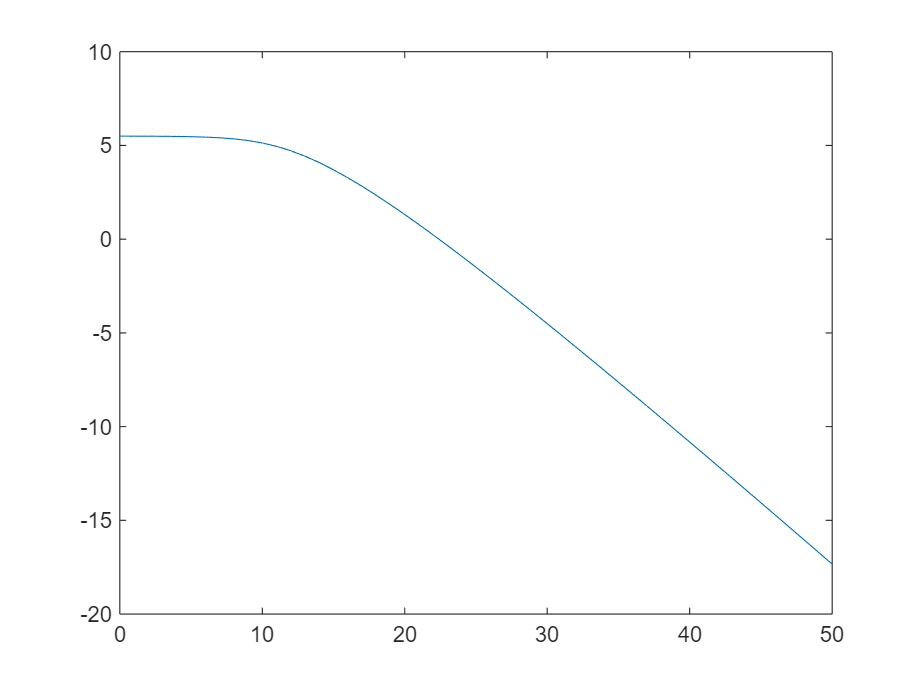

plot(V,outputCurrents);